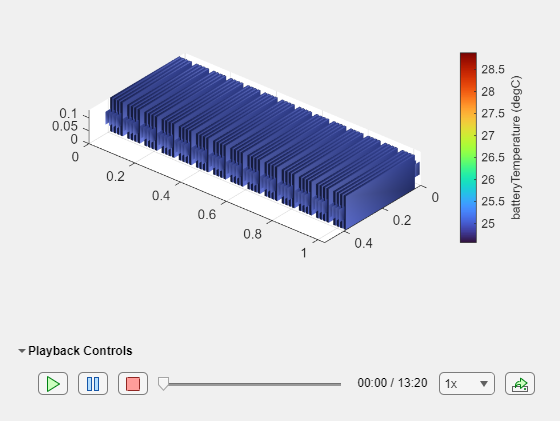

import simscape.battery.builder.*
load pouchPackExample.mat;
batterySimLog = BatterySimulationLog(ModuleAssembly1,  out.simlog.ModuleAssembly1);
% batterySimLog.SelectedVariable = "temperatureCell";
f = uifigure("Color","w");
g = uigridlayout(f, [1,1]);
moduleChart = BatterySimulationChart(Parent = g, ...
    BatterySimulationLog = batterySimLog);
moduleChartColorBar = colorbar(moduleChart);
ylabel( moduleChartColorBar, strcat(batterySimLog.SelectedVariable, " (", batterySimLog.SelectedVariableUnit,")") );